addpath(genpath(fileparts(which('aae575hw05.mlx'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
% 1 Eccentricity:                             e
% 2 Time of Applicability(s):                 TOE
% 3 Orbital Inclination(rad):                 I_0
% 4 Rate of Right Ascen(r/s):                 OMEGA_DOT
% 5 SQRT(A) (m^1/2):                          SQRT_A
% 6 Right Ascen at TOA(rad):                  OMEGA_0
% 7 Argument of Perigee(rad):                 OMEGA
% 8 Mean Anom(rad):                           M_0
% 9 mean motion diff(r/s):                    DELTA_N
% 10 Rate of inclin (r/s):                    I_DOT
% 11 lat cosine ampl (r):                     CUC
% 12 Lat sine ampl   (r):                     CUS
% 13 radius cos ampl (m):                     CRC
% 14 radius sin ampl (m):                     CRS
% 15 inclin cos ampl(r):                      CIC
% 16 inclin sin ampl(r):                      CIS
% 17 t_gd:                                    T_GD
% 18 t_oc:                                    T_OC
% 19 Af0(s):                                  af0
% 20 Af1(s/s):                                af1
% 21 Af2(s/s/s):                              af2

eph6 = importeph('ephemeris.dat',6); % PRN 6 Ephemeris Data
eph18 = importeph('ephemeris.dat',18); % PRN 18 Ephemeris Data
igs6 = extractsp3('igr11382.sp3',6); % PRN 6 IGS Orbit Data
igs18 = extractsp3('igr11382.sp3',18); % PRN 18 IGS Orbit Data

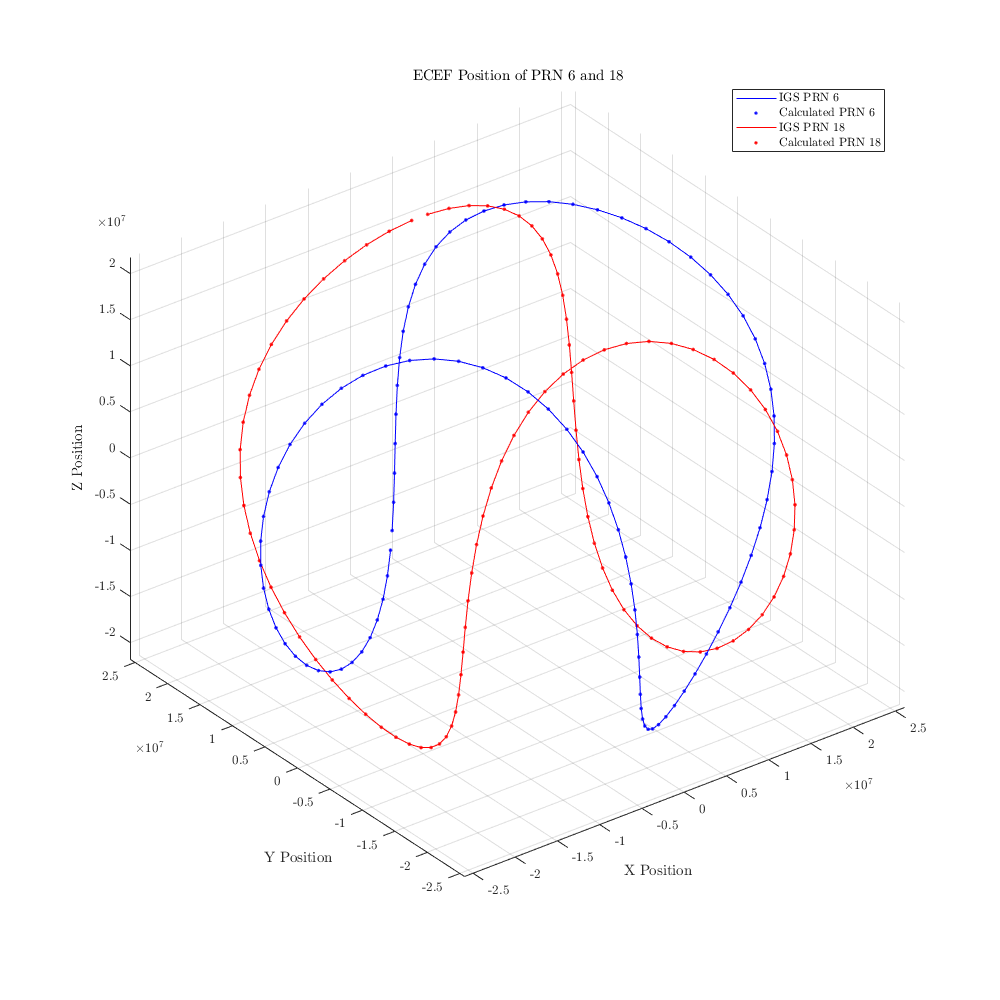

[xk6,yk6,zk6,x6,y6,z6,t6] = ECEF(6,eph6,igs6); % PRN 6 Coordinates
[xk18,yk18,zk18,x18,y18,z18,t18] = ECEF(18,eph18,igs18); % PRN 18 Coordinates
t6plot = igs6(:,2);
t18plot = igs18(:,2);
% Plotting
plot3(x6,y6,z6,'b')
hold on 
plot3(xk6,yk6,zk6,'b.')
grid on
plot3(x18,y18,z18,'r')
plot3(xk18,yk18,zk18,'r.')
legend('IGS PRN 6','Calculated PRN 6','IGS PRN 18','Calculated PRN 18',"Location","best")
xlabel('X Position')
ylabel('Y Position')
zlabel('Z Position')
title('ECEF Position of PRN 6 and 18')
axis equal
set(gcf,'position',[0,0,1000,1000])
hold off

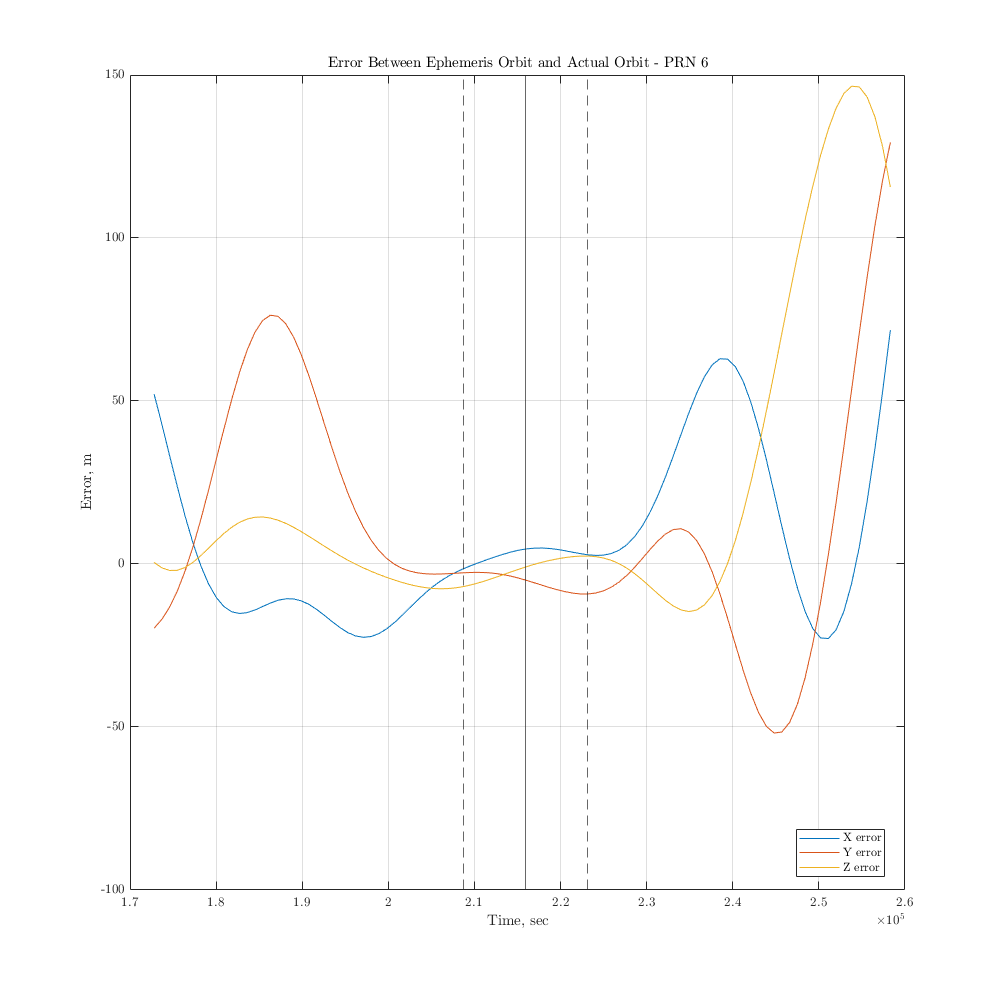

% PRN 6 Error
xe6 = x6 - xk6;
ye6 = y6 - yk6;
ze6 = z6 - zk6;
plot(t6plot,xe6)
hold on
plot(t6plot,ye6)
plot(t6plot,ze6)
title('Error Between Ephemeris Orbit and Actual Orbit - PRN 6')
xlabel('Time, sec')
ylabel('Error, m')
grid on
xline(eph6(2))
xline(eph6(2)-2*3600,'--'), xline(eph6(2)+2*3600,'--')
legend('X error','Y error','Z error','Location',"best")
hold off

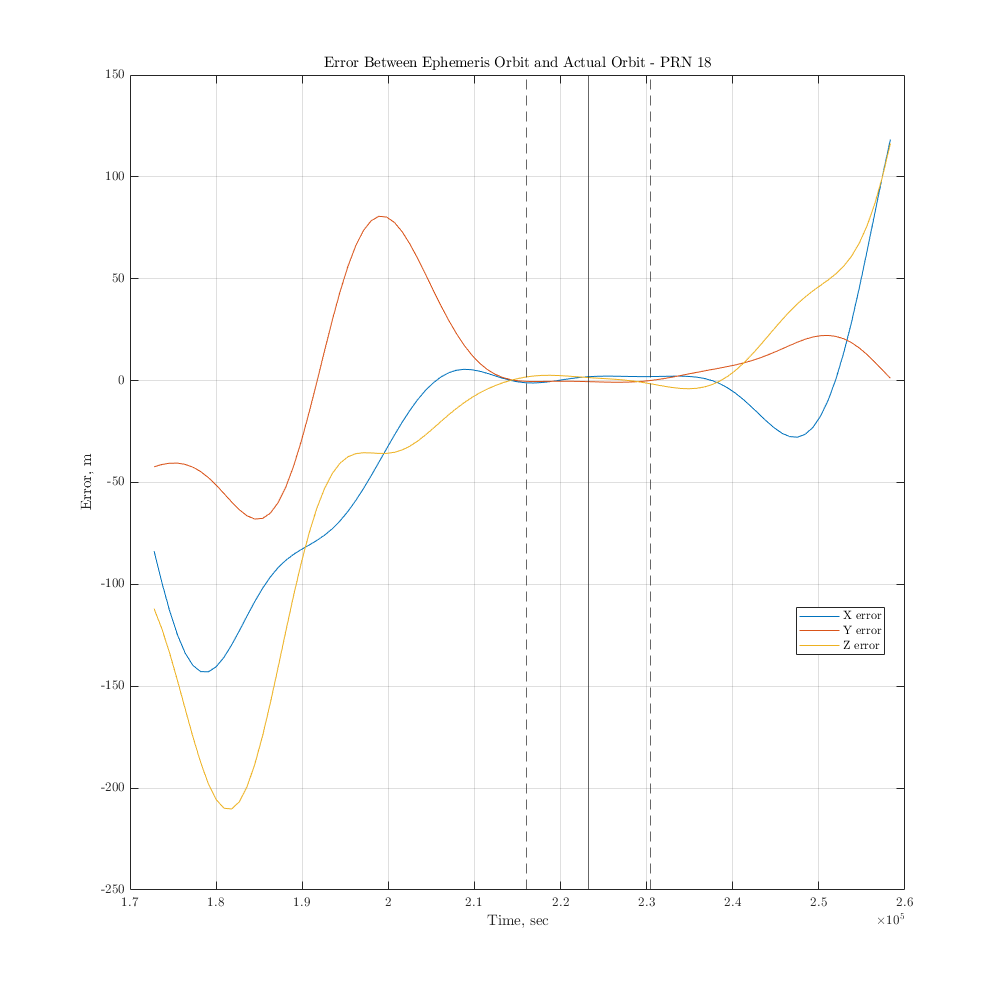

% PRN 18 Error
xe18 = x18 - xk18;
ye18 = y18 - yk18;
ze18 = z18 - zk18;
plot(t18plot,xe18)
hold on
plot(t18plot,ye18)
plot(t18plot,ze18)
title('Error Between Ephemeris Orbit and Actual Orbit - PRN 18')
xlabel('Time, sec')
ylabel('Error, m')
grid on
xline(eph18(2))
xline(eph18(2)-2*3600,'--'), xline(eph18(2)+2*3600,'--')
legend('X error','Y error','Z error','Location',"best")
hold off

% PRN 6 Error Root Mean Square
x6_rms = rootms(xe6,t6,-2*3600,+2*3600)

x6_rms =    3.605967307412405


y6_rms = rootms(ye6,t6,-2*3600,+2*3600)

y6_rms =    6.187544151536615


z6_rms = rootms(ze6,t6,-2*3600,+2*3600)

z6_rms =    3.594304931005384


% PRN 18 Error Root Mean Square
x18_rms = rootms(xe18,t18,-2*3600,+2*3600)

x18_rms =    1.698146085947368


y18_rms = rootms(ye18,t18,-2*3600,+2*3600)

y18_rms =    0.524983412685801


z18_rms = rootms(ze18,t18,-2*3600,+2*3600)

z18_rms =    1.764090523852996


## Functions

#### Function 1: Import Data from ephemeris.dat file

function ephdat = importeph(data,prn)
eph = readtable(data);
eph = table2array(eph(:,2));
n2 = 16;
% remove variable names
for i = 1:length(eph)
    temp = char(eph(i));
    if length(temp) < 4
        temp2(i) = str2double(temp);
    else
        temp2(i) = str2double(temp(1:n2));
    end
end
temp2 = temp2';
n = find(temp2 == prn);

ephdat = temp2(n:n+22);
ephdat([1 18]) = [];
end

#### Function 2: Read .sp3 Function

function [sp3] = read_sp3( filename )
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This code computes reads satellite positions from an SP3 file
%
% Inputs:   filename - filename of SP3 file
%
% Outputs:  sp3_obs = [GPS_week GPS_TOW PRN x y z], sorted by PRN #
%           *note - GPS_TOW is in seconds;  x,y,z are in km
%
% Coded by David Wiese
% Colorado Center for Astrodynamics Research 
% University of Colorado at Boulder
% October 12, 2006
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Assign a file ID and open the given header file.
fid=fopen(filename);
% If the file does not exist, display warning message
if fid == -1
    display('Error!  File does not exist.  Computer will self-detonate');
else
    % Go through the header (23 lines long)
    for i = 1:23
        current_line = fgetl(fid);
        % Store the number of satellites in the SP3 file    
        if i == 3
            current_line = current_line(2:length(current_line));
            F = sscanf(current_line,'%u');
            no_sat = F(1);
        end
        i = i + 1;
    end
    % Begin going through times and observations
    end_of_file = 0;
    i = 0; j = 1;
    while end_of_file ~= 1        
        current_line = current_line(2:length(current_line));
        F = sscanf(current_line,'%f');
        % Load GPS Gregorian time into variables
        Y = F(1);
        M = F(2);
        D = F(3);
        H = F(4);
        min = F(5);
        sec = F(6);
        Greg_time(j,:) = [Y M D H min sec];
        % Convert GPS Gregorian time to GPS week and GPS TOW
        [GPS_wk, GPS_TOW] = GPSweek(Y,M,D,H,min,sec);
        % Store satellite PRN and appropriate observations
        for n = 1:no_sat
            % Go to the next line
            current_line = fgetl(fid);
            %current_line = current_line(2:length(current_line));
            current_line = current_line(3:length(current_line));
            F = sscanf(current_line,'%f');
            % Save PRN, positions, and clock error
            PRN = F(1); x = F(2); y = F(3); z = F(4); clk_err = F(5);
            % Create observation vector
            sp3_obs_all(i+n,:) = [GPS_wk GPS_TOW PRN x y z clk_err];
            n = n + 1;
        end
        % Go to next line - check to see if it is the end of file
        current_line = fgetl(fid);
        if strfind(current_line,'EOF')
            end_of_file = 1;
        end
        i = i + n - 1;
        j = j + 1;
    end         
end
sp3.data = sp3_obs_all;
sp3.col.WEEK = 1;
sp3.col.TOW = 2;
sp3.col.PRN = 3;
sp3.col.X = 4;
sp3.col.Y = 5;
sp3.col.Z = 6;
sp3.col.B = 7;
end

#### Function 3: GPS week used in read_sp3

function [GPS_wk, GPS_sec_wk] = GPSweek(Y,M,D,H,min,sec)
% This function finds GPS week and GPS second of the week.
% Inputs are
%		(1-6)   Year, mo, day, hrs (in military time), minutes, 
%			then seconds.
% Outputs are
%		(1-2)	GPS week, and GPS seconds of the week.
format long;
if nargin==4
	min=0;
	sec=0;
end;
UT=H+(min/60)+(sec/3600);
if M > 2
	y=Y;
	m=M;
else
	y=Y-1;
	m=M+12;
end;
JD=fix(365.25*y) + fix(30.6001*(m+1)) + D + (UT/24) + 1720981.5;
GPS_wk=fix((JD-2444244.5)/7);
GPS_sec_wk=round( ( ((JD-2444244.5)/7)-GPS_wk)*7*24*3600);
end

#### Function 4: Extracting Data from the .sp3 files without column headers

function [data] = extractsp3(igsdata,n)
igr = read_sp3(igsdata);
i = find(igr.data(:,3)==n);
data = igr.data(i,:);
end

#### Function 5: ECEF Coordinates from data

function [xk,yk,zk,x,y,z,tk] = ECEF(prn,eph,igs)
% 1 Eccentricity:                             e
% 2 Time of Applicability(s):                 TOE
% 3 Orbital Inclination(rad):                 I_0
% 4 Rate of Right Ascen(r/s):                 OMEGA_DOT
% 5 SQRT(A) (m^1/2):                          SQRT_A
% 6 Right Ascen at TOA(rad):                  OMEGA_0
% 7 Argument of Perigee(rad):                 OMEGA
% 8 Mean Anom(rad):                           M_0
% 9 mean motion diff(r/s):                    DELTA_N
% 10 Rate of inclin (r/s):                    I_DOT
% 11 lat cosine ampl (r):                     CUC
% 12 Lat sine ampl   (r):                     CUS
% 13 radius cos ampl (m):                     CRC
% 14 radius sin ampl (m):                     CRS
% 15 inclin cos ampl(r):                      CIC
% 16 inclin sin ampl(r):                      CIS
% 17 t_gd:                                    T_GD
% 18 t_oc:                                    T_OC
% 19 Af0(s):                                  af0
% 20 Af1(s/s):                                af1
% 21 Af2(s/s/s):                              af2

% eph = importeph(ephdat,prn);
% igs = extractsp3(igsdat,prn);
mu = 3.986004418e14; %grav parameter
omega_dot_e = 7.2921151467e-5; %earth rotation
x = igs(:,4)*1000; y = igs(:,5)*1000; z = igs(:,6)*1000;

A = eph(5)^2; % sma
n0 = sqrt(mu/A^3); % initial mean motion
tk = igs(:,2) - eph(2); % time
n  = n0 + eph(9); % corrected mean motion
Mk = eph(8) + n*tk; % mean anomaly

e = eph(1); % eccentricity
for i = 1:length(Mk)
    Ek(i) = Eapprox(Mk(i),e);
end
Ek = Ek'; % eccentric anomaly
vk = 2*atan(sqrt((1+e)/(1-e))*tan(Ek/2)); % true anomaly

latk = vk + eph(7); % latitude uncorrected
cuc = eph(11); cus = eph(12); crc = eph(13); crs = eph(14); cic = eph(15); cis = eph(16);

% Perturbations
duk = cus*sin(2*latk)+cuc*cos(2*latk);
drk = crs*sin(2*latk)+crc*cos(2*latk);
dik = cis*sin(2*latk)+cic*cos(2*latk);

% Corrected Lat, rad, inc
uk = latk+duk;
rk = A*(1-e*cos(Ek))+drk;
ik = eph(3) + dik + eph(10)*tk;

% coordintates in orbital plane
xkp = rk.*cos(uk);
ykp = rk.*sin(uk);

% longitude of AN
omk = eph(6) + (eph(4) - omega_dot_e).*tk - omega_dot_e * eph(2);

% DCM conversion to ECEF
xk = xkp .* cos(omk) - ykp .* cos(ik) .* sin(omk);
yk = xkp .* sin(omk) + ykp .* cos(ik) .* cos(omk);
zk = ykp .* sin(ik);
end

#### Function 6:  Approximation of Eccentric Anomaly

function E = Eapprox(Mk,e)
% Mk is a constant

E = Mk;
for j = 1:10
    E = E + (Mk - E + e*sin(E))/(1-e*cos(E));
end
end

#### Function 7: Root Mean Square

function rms = rootms(x,t,t0,tf)
t0ind = closeto(t,t0);
tfind = closeto(t,tf);
n = abs(tfind-t0ind);
rms = sqrt(1/n * sum(x(t0ind:tfind).^2));
end

#### Function 8: Closest function

function ind = closeto(x,xi)
error = abs(x-xi);
min_error = min(error);
ind = find(error == min_error);
end